Для частицы массы m0 в 1dPW с бесконечно высокими стенками при x = 0 и x = L = 101A построить аналитическим и численным N = 100 методами распределение плотности вероятности для n = 1 и n = 25.

clc, clear, close all
datetime('now')

ans = datetime
   04-Jun-2023 15:35:05



addpath('C:\Users\emill\Desktop\IORN\L07');
load('constance.mat', 'hbar', 'm0', 'J2eV');

L = 101 * 1e-10;
N = 100;
n_1 = 1;
n_2 = 25;
x = linspace(1e-10, L, N);

Analytical method

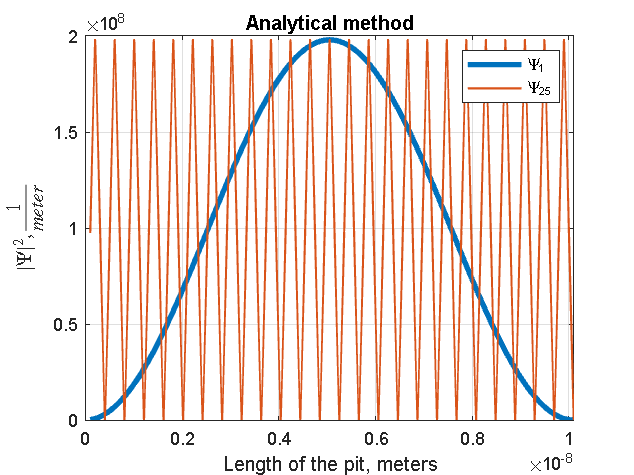

Psi_1_an = sqrt(2 / L) * sin(pi * n_1 * x ./ L);
Psi_2_an = sqrt(2 / L) * sin(pi * n_2 * x ./ L);

plot(x, abs(Psi_1_an) .^2, 'LineWidth', 3);
hold on;
plot(x, abs(Psi_2_an) .^2, 'LineWidth', 1.2);

xlabel("Length of the pit, meters");
ylabel("$|\Psi|^2, {1\over meter}$", 'Interpreter','latex');
legend("\Psi_{1}", "\Psi_{25}");
title('Analytical method');
grid on;
xlim([0, L]);

hold off;

Numerical method

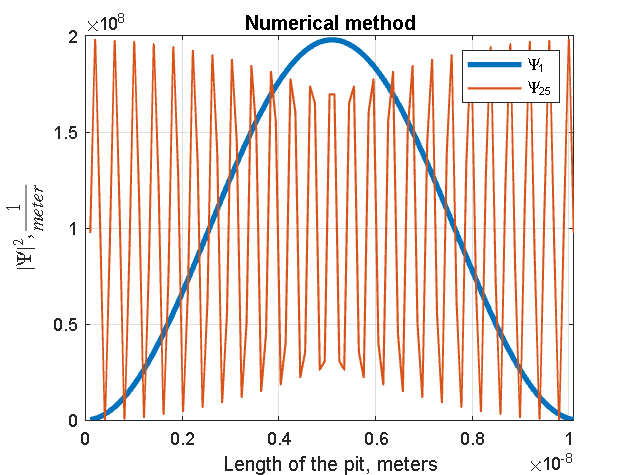

t = hbar ^ 2 / ((L / (N + 1)) ^ 2 * 2 * m0);
v_1 = 2 * t * ones(1, N);
v_2 = -t * ones(1, N - 1);
H = diag(v_1) + diag(v_2, 1) + diag(v_2, -1);
[V, D] = eig(H);

Psi_1_num = V(:, 1)';
Psi_2_num = V(:, 25)';

plot(x, abs(Psi_1_num) .^2 / (L / (N + 1)), 'LineWidth', 3);
hold on;
plot(x, abs(Psi_2_num) .^2 / (L / (N + 1)), 'LineWidth', 1.2);

xlabel("Length of the pit, meters");
ylabel("$|\Psi|^2, {1\over meter}$", 'Interpreter','latex');
legend("\Psi_{1}", "\Psi_{25}");
title('Numerical method');
grid on;
xlim([0, L]);

hold off;

Сравнение энергий

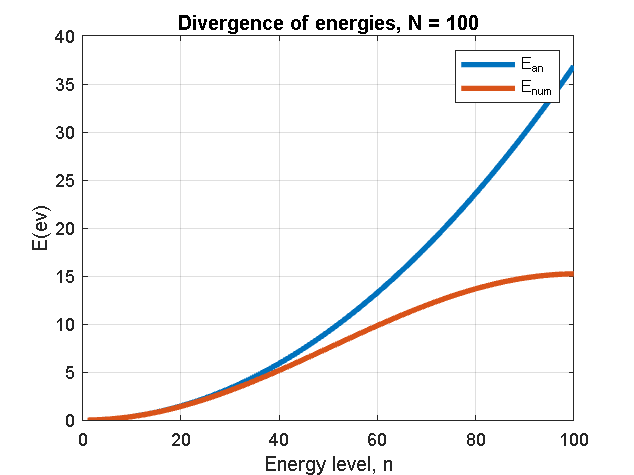

n = linspace(1, 100, N);
E_an = t * (pi * L / (N + 1) * n ./ L) .^ 2 * J2eV;
E_num = 2 * t * (1 - cos(pi * L / (N + 1) * n ./ L)) * J2eV;
plot(n, E_an, 'LineWidth', 3);
hold on;
plot(n, E_num, 'LineWidth', 3);

xlabel('Energy level, n');
ylabel('E(ev)');
legend('E_{an}', 'E_{num}');
title('Divergence of energies, N = 100');
xlim([0, 100]);
grid on;
hold off;

Подбор шага

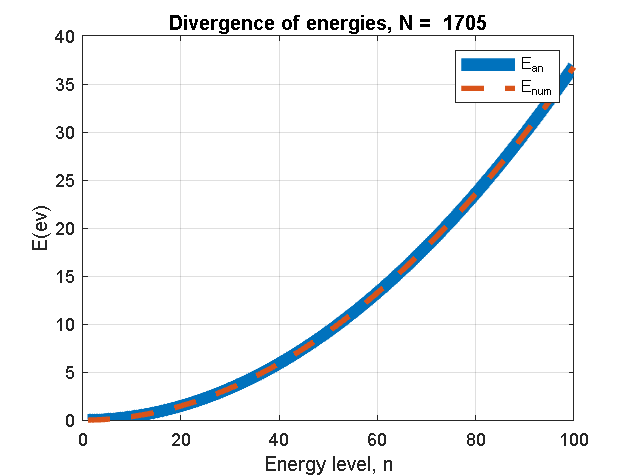

k = n * pi / L;
E_1 = cos(k * L / (N + 1));
E_2 = 1 - k .^2 * (L / (N + 1)) ^ 2 / 2;

ref = linspace(true, true, N);
check = E_1 - E_2 <= 1e-9;

if(~isequal(check, ref))
    for i = 1 : numel(k)
        while(abs(E_1(i) - E_2(i)) > 1e-9)
            N = N + 1;
            n = linspace(1, 100, N);
            k = n * pi / L;
            E_1 = cos(k * L / (N + 1));
            E_2 = 1 - k .^2 * (L / (N + 1)) ^ 2 / 2;
        end
    end
    
    t = hbar ^ 2 / ((L / (N + 1)) ^ 2 * 2 * m0);
    E_an = t * (pi * L / (N + 1) * n ./ L) .^ 2 * J2eV;
    E_num = 2 * t * (1 - cos(pi * L / (N + 1) * n ./ L)) * J2eV;
    
    plot(n, E_an, 'LineWidth', 7);
    hold on;
    plot(n, E_num, 'LineWidth', 3, 'LineStyle', '--');
    
    xlabel('Energy level, n');
    ylabel('E(ev)');
    legend('E_{an}', 'E_{num}');
    title(strjoin({'Divergence of energies, N = ', num2str(N)}));
    xlim([0, 100]);
    grid on;
    hold off;
else
    disp('Расхождение мало');
end